**Giordano Dylan - Martelet Curtis                            M1 EEA Grp C**

# Rapport TP3: Filtrage sur Hacheur série/Hacheur entrelacés 2 voies

## Partie 1: Hacheur série simple

Résistance parasite: $R=\frac{U}{I}=\frac{0\ldotp 25}{2}=0\ldotp 125\Omega$.

Mesure de L: Nous mesurons le $\Delta I_L$ graces aux curseurs de l'oscilloscope : nous relevons 3.625A.

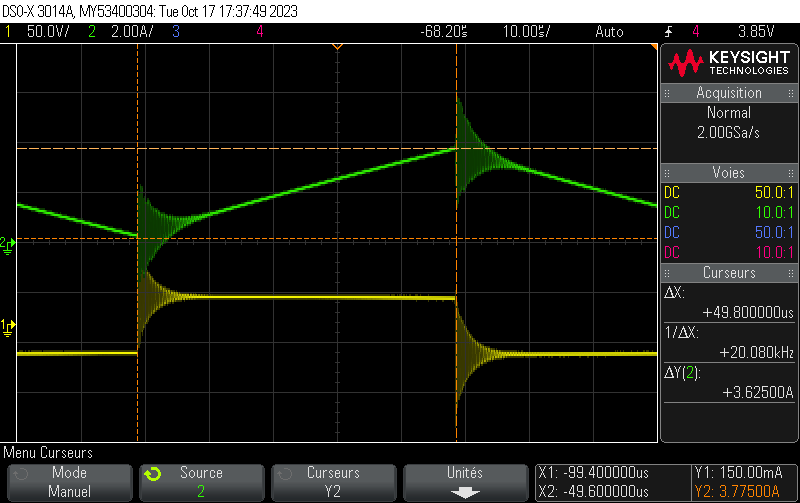


$$\Delta I_{L\;\textrm{Prattique}} =3,625A\;;V_{L\;\textrm{pratique}} =55V\;;F_{\textrm{dec}} =10\textrm{kHz}$$


On prend le rapport cyclique pour le cas le plus défavorable, c'est à dire 0.5.

On a $V_L =V_E$ pour $0<T<\alpha T$ : $V_L =\frac{L\times \Delta I_L }{\alpha T}\iff L=\frac{\alpha V_L }{\Delta I_L \times F_{\textrm{dec}} }=\frac{55\times 0,5}{3,625\times 10\textrm{e3}}=0,758\textrm{mH}$.


$$\Delta I_{L_{\max } } =\frac{\alpha V_E }{L\times F_{\textrm{dec}} }=\frac{55}{2\times 1e-3\times 10\textrm{e3}}=3\ldotp 627A$$


Expérimentalement, nous relevons une ondulation de courant égale à 3.625A. 

Pour le cas le plus défavorable, on prend $\alpha =0,5$.


$$\Delta V_C =\frac{\Delta I_L }{8\times C\times F_{\mathrm{dec}} }\iff C=\frac{\Delta I_L }{\Delta V_C \times F_{\mathrm{dec}} }=\frac{3\ldotp 627}{8\times 1\ldotp 2\times 10\mathrm{e3}}=37\ldotp 7\mu F$$


De manière pratique, nous devons avoir un condensateur de sortie égal à $35\mu F$pour que l'ondulation de la tension de sortie soit égale à 1.2V.

## Partie 2: Hacheurs série entrelacés

Résistance parasite : $R_{\textrm{parasite}} =125m\Omega$. On a deux montage d'inductance en série, donc $R_{\textrm{parasite}}^{\prime } =2\times R_{\textrm{parasite}} =125\times 2=250m\Omega$.


$$L^{\prime } =940\mu H$$


Pour le hacheur série classique : $W_{L_{\max } } =\frac{L\times {i_{L_{\max } } }^2 }{2}=0\ldotp 00534$ & $W_{C_{\max } } =\frac{C\times {v_{C_{\max } } }^2 }{2}$

Pour les hacheurs série entrelacés : $W_{L_{\max } } =\frac{L\times {i_{L_{\max } } }^2 }{2}=0\ldotp 00534$ & $W_{C_{\max } } =\frac{C\times {v_{C_{\max } } }^2 }{2}$

## Partie 3: Comparaison entre les deux montages

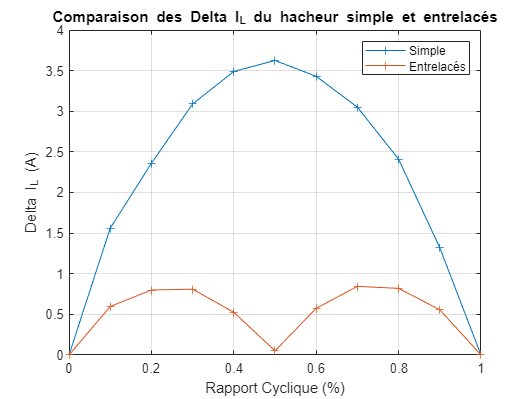

%Hacheur série
alpha=[0 0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1];
delta_iL=[0 1.56 2.36 3.09 3.49 3.625 3.43 3.05 2.41 1.32 0];
delta_Vs=[0 0.56 0.787 1.00 1.13 1.175 1.125 1.02 0.781 0.55 0];

%Hacheur série entrelacé:
delta_iL_e=[0 0.597 0.800 0.810 0.525 0.052 0.575 0.845 0.820 0.557 0];
delta_Vs_e=[0 0.128 0.152 0.146 0.091 0.030 0.125 0.147 0.143 0.091 0];


plot(alpha,delta_iL,'+-',alpha,delta_iL_e,'+-');
title('Comparaison des Delta I_L du hacheur simple et entrelacés')
xlabel('Rapport Cyclique (%)'); ylabel('Delta I_L (A)');legend("Simple","Entrelacés")
grid on

On peut observer que 

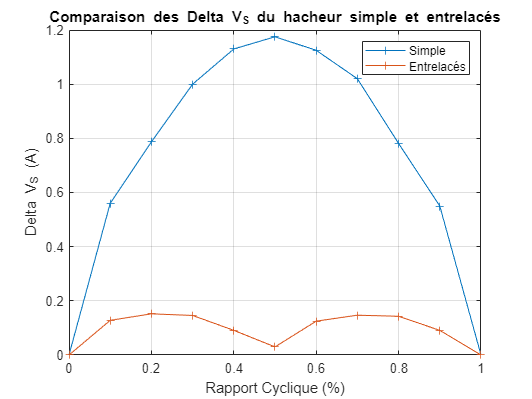

plot(alpha,delta_Vs,'+-',alpha,delta_Vs_e,'+-');
title('Comparaison des Delta V_S du hacheur simple et entrelacés')
xlabel('Rapport Cyclique (%)'); ylabel('Delta V_S (A)');legend("Simple","Entrelacés")
grid on